# **ACM 11 Homework 1 Part 1/2 (Spring 2024)**

## **Due Friday, April 12, 11:59pm Pacific Time, by upload to Canvas.**

This assignment is worth$100$ points in total. The points in Part 1 of the homework make up $75$ of 100 total points. The points in this file add up to 50 points - if your code completes the task correctly then you will receive the full 50 points for credit. Then,

- An additional $5$ points are allocated to readable code. 

- A further $5$ points are allocated to efficient code (unless explicitly instructed to write inefficient code).

- The final $15$ points for the written answers to the questions in the code being clear, correct, and in complete sentences.

### Problem 1 (5 points)

Use the `disp` command to write a "Hello World" program in the following block.

disp('Hello World');

Hello World


### **Problem 2 (Fibonacci sequence, 10 points)**

The classical Fibonacci sequence of integers is defined via the following recursive relation:


$$F_{m+2} = F_{m+1}+F_{m} \  (m \geq 1), \ F_{1}=F_{2}=1$$


Write a script that uses a for loop to compute the first $$n = 20$$ terms $$\{F_{m}\}_{m=1}^{n}$$ in the Fibonacci sequence in the following block. Use the `zeros` command to pre-allocate a $20 \times 1$ array for all the terms of the sequence. Suppress the output within your for loop but display all computed elements at the end.

result = zeros(20, 1);
first = 1;
second = 1;
result(1) = first;
result(2) = second;
for i = 1:20
    result(i+2) = first+second;
    temp = first;
    first = second;
    second = second + temp;
end
for i = 1:20
    disp(result(i));
end

     1

     1

     2

     3

     5

     8

    13

    21

    34

    55

    89

   144

   233

   377

   610

   987

        1597

        2584

        4181

        6765



As a check of your work, the $20$-th Fibonacci number is $6765$. Compare the $20$-th element of your Fibonacci array by subtracting it from the true answer -- the error should be $0$:

6765 - result(20)

ans = 0

### **Problem 3 (Pre-allocation, 15 points)**

Here we will use a toy example to illustrate how preallocation can help optimize your MATLAB code. In your later work, you should always try preallocating the maximum amount of space required for an array at first instead of continuously resizing the array.

Consider a sequence $$\{x_{k}\}_{k=1}^{\infty}$$ defined as follows:


$$$x_{k+1} = \frac{1}{2}(x_{k}^2-x_{k}+2), \ x_{1} = \frac{3}{2}$$$


We want to compute the first $$10^6$$ terms in this sequence and store them in a row vector.

**(5 points) **Initialize the final output as a scalar and append a new term to it in each round of the loop. Record the running time (Hint: try using "tic" and "toc" ) Please write your code in the following block:

answer = 3/2;
num = 3/2;
tic;
for i = 2:10^6
    num = 0.5*(num^2 - num + 2);
    answer = [answer, num];
end
time = toc;
disp(time);

  202.4166



**(5 points) **Initialize the final output as an array with the desired size and update one term in the array in each round of the loop. Please write your code in the following block:

final = zeros(10^6, 1);
number = 3/2;
final(1) = number;
tic;
for i = 2:10^6
    number = 0.5*(number^2 - number + 2);
    final(i) = number;
end
elapsed = toc;
disp(elapsed);

    0.0183



**(5 points) **Compare the two running times you recorded above. Briefly discuss what you observed. (Please write your discussion in the string in the following block.)

disp(['The running time of the second method' ...
    'is much smaller than that of the first one,' ...
    'showing that it is much more efficient to ' ...
    'first allocate the appropriate space, rather' ...
    'than coninuously expanding the data structure.'])

The running time of the second methodis much smaller than that of the first one,showing that it is much more efficient to first allocate the appropriate space, ratherthan coninuously expanding the data structure.


### **Problem 4 (Plotting a line, 10 points)**

We want to plot the line $y=m\;x+b$ for different values of $m$. In the following block, fix $b=2\ldotp 2$ and loop through $6$ values of $m$ between $1$ and $3$, and plot $y$ vs. $x$ on the same axis for $x$ in $[0,1]$ in different colors using the hold command. Label your axes and give the plot a title. Include an appropriate legend.

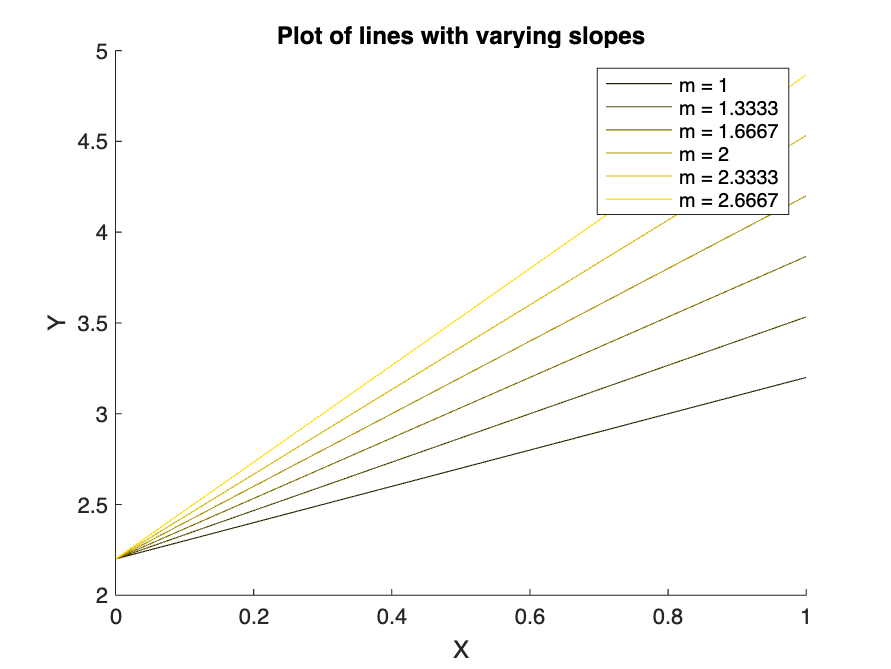

b = 2.2;
x = linspace(0, 1, 10);
plots = zeros(1, 6);
labels = cell(1, 6);
hold on;
for i = 1:6
    y = (1 + (i-1)/3)*x + b;
    plots(i) = plot(x, y, 'Color', [i/6 i/7 0]);
    labels{i} = ['m = ', num2str(1 + (i-1)/3)];
end
hold off;
title('Plot of lines with varying slopes');
xlabel('X');
ylabel('Y');
legend(plots, labels);

### **Problem 5 (Plotting a multivariate function, 10 points)**

We want to plot the function $z=m{\;}_1 x+m_2 y^2$ for $(x,y)$ in $[0,1] \times [-0.5,0.5]$ (i.e. on the unit square). We will use $m_1 =2$ and $m_2 =3$. We will do this several ways. 

**(3 points) **First, define an array of $x$-values from $0$ to $1$  with $10$ points, and an array of y-values from $-0.5$ to $0.5$ with $15$ points. Pre-allocate an $15 \times 10$ array for $z$, and **loop** through every combination of $x$- and $y$-values to fill in the $z$ array. Use the tic/toc commands to time how long this takes. Then use the surf command to plot $z$ vs. $x$ and $y$. Label your axes. 

x = linspace(0, 1, 10);
y = linspace(-0.5, 0.5, 15);
z = zeros(15, 10);
tic;
for i = 1:10
    for j = 1:15
        z(j, i) = 2*x(i) + 3*(y(j)^2);
    end
end
finalTime = toc;
disp(finalTime);

    0.0032



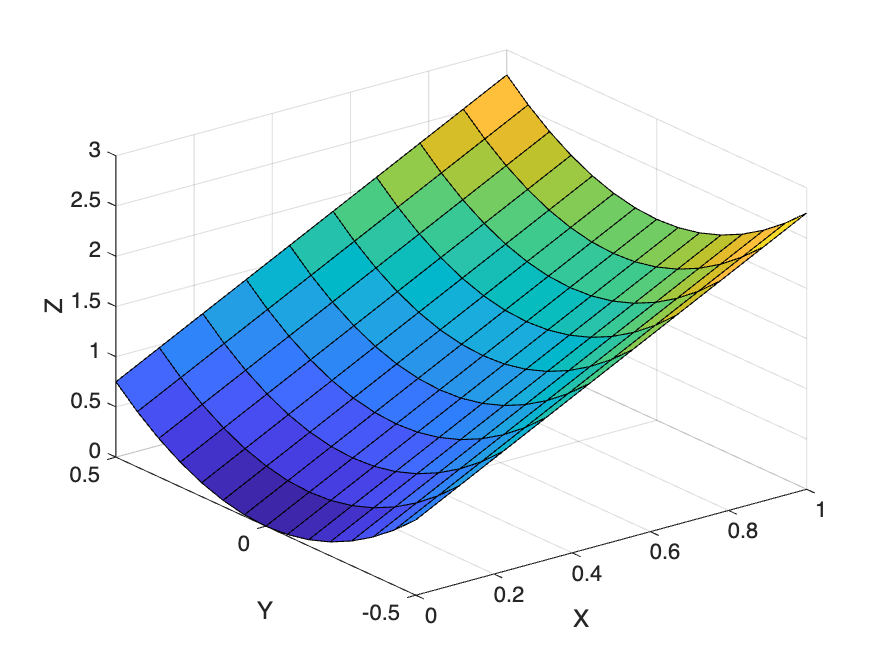

surf(x, y, z);
xlabel('X');
ylabel('Y');
zlabel('Z');

**(4 points) **Now compute the values of the $z$-array for the above function above in one line, without using a loop. Use the tic/toc commands to time how long this takes. Use the surf command to plot $z$ vs. $x$ and $y$ again. It should look identical to your above plot (otherwise you need to check your code!).

x = linspace(0, 1, 10);
y = linspace(-0.5, 0.5, 15);
z = zeros(15, 10);
[X, Y] = meshgrid(x, y)

X =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000
         0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8

Y =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286   -0.4286
   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571   -0.3571
   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857   -0.2857
   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143   -0.2143
   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429
   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714   -0.0714
         0         0         0         0         0         0         0         0         0         0
    0.0714    0.0714    0.0714    0.0714    0.0714    0.0714    0.0714    0.0714    0.0714    0.0714
    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1

tic;
z = 2*X + 3*Y.^2

z =     0.7500    0.9722    1.1944    1.4167    1.6389    1.8611    2.0833    2.3056    2.5278    2.7500
    0.5510    0.7732    0.9955    1.2177    1.4399    1.6621    1.8844    2.1066    2.3288    2.5510
    0.3827    0.6049    0.8271    1.0493    1.2715    1.4938    1.7160    1.9382    2.1604    2.3827
    0.2449    0.4671    0.6893    0.9116    1.1338    1.3560    1.5782    1.8005    2.0227    2.2449
    0.1378    0.3600    0.5822    0.8044    1.0266    1.2489    1.4711    1.6933    1.9155    2.1378
    0.0612    0.2834    0.5057    0.7279    0.9501    1.1723    1.3946    1.6168    1.8390    2.0612
    0.0153    0.2375    0.4598    0.6820    0.9042    1.1264    1.3486    1.5709    1.7931    2.0153
         0    0.2222    0.4444    0.6667    0.8889    1.1111    1.3333    1.5556    1.7778    2.0000
    0.0153    0.2375    0.4598    0.6820    0.9042    1.1264    1.3486    1.5709    1.7931    2.0153
    0.0612    0.2834    0.5057    0.7279    0.9501    1.1723    1.3946    1.6168    1.8

Time = toc;
disp(Time);

    0.0101



surf(x, y, z);
xlabel('X');
ylabel('Y');
zlabel('Z');

**(3 points) **Finally, define an anonymous function $f(x,y)$ to compute $z$ as defined above, and use the built-in function` fsurf `to plot this function on the domain $[0,1] \times [-0.5,0.5]$. How does this plot compare to your plots above? (Please write your discussion in the string in the following block.)

f = @(x, y) 2*x + 3*y^2;
fsurf(f, [0, 1, -0.5, 0.5]);

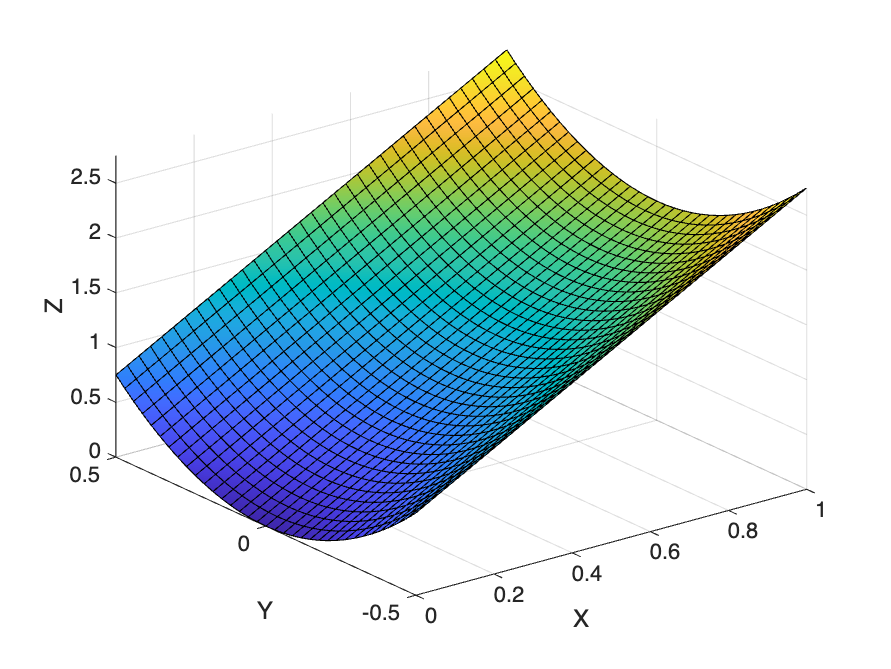

xlabel('X');
ylabel('Y');
zlabel('Z');

disp(['This plot is different from the previous ones because the grid' ...
    'of x and y values has much smaller increments. This means that' ...
    'definiing the anonymous function automatically creates smaller' ...
    'intervals on the x and y domains for which the function is evaluated.'])

This plot is different from the previous ones because the gridof x and y values has much smaller increments. This means thatdefiniing the anonymous function automatically creates smallerintervals on the x and y domains.
